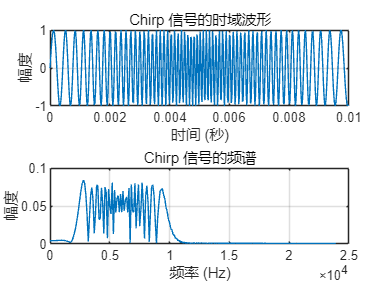

% 1. 读取保存的preamble.csv文件
preamble = csvread('preamble.csv');

% 2. 定义采样率
fs = 48000; % 采样率为48000 Hz

% 3. 计算时间轴
t = (0:length(preamble) - 1) / fs;


% % Preamble: 440 samples
% f_p = [linspace(10*10^3-8*10^3,10*10^3,220), linspace(10*10^3,10*10^3-8*10^3,220)]; 
% omega = 2*pi .* cumtrapz(t(1:440), f_p);
% preamble = sin(omega);


% 4. 绘制时域信号
figure;
subplot(2,1,1); % 创建一个2行1列的子图，绘制第一个图
plot(t, preamble);
xlabel('时间 (秒)');
ylabel('幅度');
title('Chirp 信号的时域波形');
grid on;

% 5. 进行FFT计算
N = length(preamble);          % 信号长度
Y = fft(preamble);             % 对信号进行FFT
Y = Y(1:floor(N/2));            % 取前一半（对称部分）
P2 = abs(Y) / N;                % 双边频谱
P1 = P2;                         % 单边频谱（幅度）
f = fs*(0:(floor(N/2)-1))/N;    % 频率轴

% 6. 绘制频谱图
subplot(2,1,2); % 绘制第二个子图
plot(f, P1);
xlabel('频率 (Hz)');
ylabel('幅度');
title('Chirp 信号的频谱');
grid on;

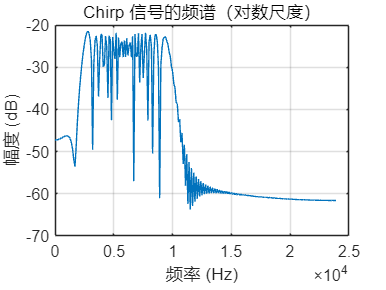


% 可选：使用对数尺度绘制频谱
figure;
plot(f, 20*log10(P1));
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('Chirp 信号的频谱（对数尺度）');
grid on;

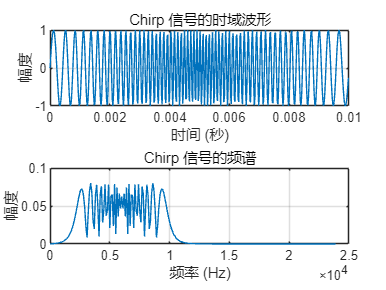

% 检查我写的chirp和matlab生成的chirp信号相关程度
clear all
% 1. 读取保存的preamble.csv文件
preamble = csvread('preamble_p1.csv');

% 2. 定义采样率
fs = 48000; % 采样率为48000 Hz

% 3. 计算时间轴
t = (0:length(preamble) - 1) / fs;


% % Preamble: 480 samples
f_p = [linspace(10*10^3-8*10^3,10*10^3,240), linspace(10*10^3,10*10^3-8*10^3,240)]; 
omega = 2*pi .* cumtrapz(t(1:480), f_p);
preamble = sin(omega);


% 4. 绘制时域信号
figure;
subplot(2,1,1); % 创建一个2行1列的子图，绘制第一个图
plot(t, preamble);
xlabel('时间 (秒)');
ylabel('幅度');
title('Chirp 信号的时域波形');
grid on;

% 5. 进行FFT计算
N = length(preamble);          % 信号长度
Y = fft(preamble);             % 对信号进行FFT
Y = Y(1:floor(N/2));            % 取前一半（对称部分）
P2 = abs(Y) / N;                % 双边频谱
P1 = P2;                         % 单边频谱（幅度）
f = fs*(0:(floor(N/2)-1))/N;    % 频率轴

% 6. 绘制频谱图
subplot(2,1,2); % 绘制第二个子图
plot(f, P1);
xlabel('频率 (Hz)');
ylabel('幅度');
title('Chirp 信号的频谱');
grid on;

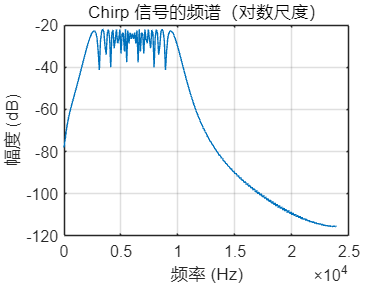


% 可选：使用对数尺度绘制频谱
figure;
plot(f, 20*log10(P1));
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('Chirp 信号的频谱（对数尺度）');
grid on;